# Designing a convolutional neural network for hand-written digits classification

Michele Marolla

This is the technical project for *Machine Learning and Applications* exam, at University Federico II, Naples.

A generic convolutional neural network is designed and implemented from scratch as a stand-alone library. Then, it is trained in order to recognize raw images of hand-written digits, and its performances are evaluated. In particular, the *MNIST* dataset has been used (for further information, see here: [http://yann.lecun.com/exdb/mnist/](http://yann.lecun.com/exdb/mnist/)).

For this project, *MATLAB* has been chosen due to its strong support on matrix algebra. This document has been written using *MATLAB Live Script.*

## Designing and implementing a multi-layer neural network

**Network** is a handle class that implements a multi-layer feed-forward neural network. Every *Network* has two public properties: a *name* string, that let the user define the name of the network, and a cell array of *Layer* objects.

**Layer** is a value class that implements a single layer of nodes. It contains a matrix of weights and biases, values used for *resilient back-propagation*, and names and pointers to activation and output functions. It is possible to arbitrarly assign any activation and output function to each layer: by default, sigmoid is used for internal layers and identity for output layers.

For further information on the single functions, their parameters and default values, see the .m code files: they are extensively commented.

#### Forward propagation

In order to create a new *Layer*, you need to define a weight matrix (dimensions equal to number of nodes x numbers of inputs), biases column vector (dimensions equal to number of nodes), the activation function and output function (both as strings). The identity function (*"identity"*), the Rectified Linear Unit (*"ReLU"*) and the sigmoid (*"sigmoid"*) have already been implemented. However, you can define whatever function you want inside a .m file and pass their name. Sigmoid and identity .m function file has been created as an example.

%% Creating a layer with 3 nodes and 5 inputs, using sigmoid as activation function
%% and identity as output function
W = randn(3,5);
B = randn(3,1);
MyLayer = Layer(W,B,"sigmoid","identity");

Layer's function *compute *is used to compute the output of that single layer, given the input. The input must be in form a vector, with dimension coherent with the weight matrix (it can be indifferently a row or column vector). The output is returned as a column vector, with dimension equal to the number of nodes.

%% Example: compute
Input = randn(1,5);
LayerOutput = MyLayer.compute(Input);

In order to create a *Network *you need to specify:

- Input dimension (integer)

- Layers number and dimensions as a vector containing the number of nodes for each layer (example: *[3 2]* defines two layers, the first with 3 nodes and the second with 2 nodes).

Other optional parameters are:

- Output function of each layer, as a vector of string. Identity is used by default.

- Activation function of each layer, as a vector of string. By default, sigmoid is used for internal layers and identity for the last layer.

- Error function used for learning: cross entropy with softmax (default) and sum of squares have already been implemented, but the user can define an arbitrary function.

- The derivative of the error function; this must be specified if the user has defined an own error function.

- A cell array of dimensions equal to the number of layers containing matrices that specify which connection are enabled. Each matrix must have the same dimensions of layers' weight matrices: the element *(i,j)* must have value 1 if there is a connection between node *i* and node *j*, 0 otherwise. By default, the network is full connected (i.e., the matrix has all the elements equal to 1).

% Creating a full-connected network with 3 layers, with 3, 4 and 5 nodes
% respectively, and 10 inputs.

MyNetwork = Network(10, [3,4,5]);
MyNetwork.name = 'MyNetwork';

Network's *forward *function computes the forward propagation inside the network, given an input vector of suitable dimension (equals to the number of columns of the weight matrix of the first layer). Two values are returned: a row vector containing the outputs of the last layer, and a cell array containing the outputs (as row vectors) of each internal layer.

% Example: forward

Input = randn(1,10);
[output, LayersOutput] = MyNetwork.forward(Input);

The *reset *function resets weights and biases with random values for each layer.

% Example: reset
MyNetwork.reset();

The *setConnectionMap* function takes a cell array that specify which connection to enable / disable in the network. Again, value 1 enable the connection and 0 disable it.

% Example: setConnectionMap. Remove the connection of the first node of first layer
% with the first 5 inputs
for i = 1:length(MyNetwork.layers)
    FC{i} = ones(size(MyNetwork.layers{i}.W));
end
FC{1}(1,1:5) = 0;
MyNetwork.setConnectionMap(FC);

#### Back propagation

The learning phase is activated by using the **learn **function. Besides the training and validation set, it also accepts a number of optional parameters, so that the user can specify:

- the number of epochs (default: 1000)

- the learning rate $\eta \;$(scalar) for the gradient descent method, or the vector $\left\lbrack \eta^- \;\;\;\eta^+ \right\rbrack$ for the resilient back-propagation (default: gradient descent with $\eta =0\ldotp 0005$)

- in case of mini-batch approach, the number of elements for each subdivision; if equal to -1, the batch approach is used (default: -1)

- weight-decay coefficient (default: 0)

- moment coefficient (default: 0)

- an early stopping criterion (default: empty). At the current state, two different criteria has been implemented: *"firstMin"*, for which the learning is ended when the first minimum is encountered; *"stopEpochs"*, for which the learning is ended if the validation error does not improve after a specified number of consecutive epochs.

The learn functions returns three outputs: an array of error values on the training set for each epoch, an array of errors on the validation set, and the best network corresponding to the minimum error on the validation set.

In the next two paragraphs, you can find some examples where the learn function is used.

To implement the learning phase, two private function has been implemented too: one for computing the $\delta \;$ values for each node, and one for computing the derivatives of the error function through back-propagation. For further information, see the comments in the *Network.m* file.

The user can specify an arbitrary error function through *setErrorFunction*, that takes three input parameters:

- the error function name, that could be "*crossEntropy"* or *"sumOfSquares" *(these are already implemented), or the name of a function written by the user

- the name of the function that computes the derivative of the error (mandatory only for user-defined functions)

- a flag that enable or disable a softmax post-processing (mandatory only for user-defined functions)

For example, in order to specify an error function that needs softmax, you can write:

MyNetwork.setErrorFunction("myError", "myErrorDerivative", 1);

#### A test on a simple dataset: IRIS

We want now to test the network on a simple dataset: IRIS contains information on three different species of flowers. It contains 150 entries, each of them with 4 different features.

DS = readmatrix('iris.data', 'FileType', 'text');
X = DS(:,1:4);
T = (getTargetsFromLabels(DS(:,5)))';

Let's build a network called *'iris_net'*, with 4 inputs, 10 internal nodes and 3 outputs:

net = Network(4, [10 3]);
net.name = "iris_net";

A random shuffle of the dataset is executed; then, 100 elements are used for the training set, and 50 for the validation set.

% Shuffle
perm = randperm(length(X));
X = X(perm,:);
T = T(perm,:);

% Training set
X_t = X(1:100,:);
T_t = T(1:100,:);

% Validation set
X_v = X(101:150,:);
T_v = T(101:150,:);

The network will now learn using a batch approach, learning rate $\eta =0\ldotp 0005$, for 200 epochs. Training and validation error are plotted.

[t_err, v_err, best_net] = net.learn(X_t, T_t, X_v, T_v, 200, 0.0005);

init err: 242.6971
epoch: 1, train_err: 174.8949, val_err: 123.7709
epoch: 2, train_err: 133.1531, val_err: 93.5188
epoch: 3, train_err: 116.4869, val_err: 79.7034
epoch: 4, train_err: 108.5775, val_err: 70.8081
epoch: 5, train_err: 105.9817, val_err: 64.8145
epoch: 6, train_err: 105.0416, val_err: 61.2735
epoch: 7, train_err: 103.5415, val_err: 59.0438
epoch: 8, train_err: 101.7178, val_err: 57.359
epoch: 9, train_err: 99.9225, val_err: 55.9496
epoch: 10, train_err: 98.2647, val_err: 54.7283
epoch: 11, train_err: 96.7602, val_err: 53.6569
epoch: 12, train_err: 95.3991, val_err: 52.7111
epoch: 13, train_err: 94.1658, val_err: 51.8717
epoch: 14, train_err: 93.0451, val_err: 51.1226
epoch: 15, train_err: 92.0229, val_err: 50.4503
epoch: 16, train_err: 91.0871, val_err: 49.8435
epoch: 17, train_err: 90.2271, val_err: 49.2928
epoch: 18, train_err: 89.4343, val_err: 48.7905
epoch: 19, train_err: 88.701, val_err: 48.3303
epoch: 20, train_err: 88.0209, val_err: 47.9067
epoch: 21, train_err: 8

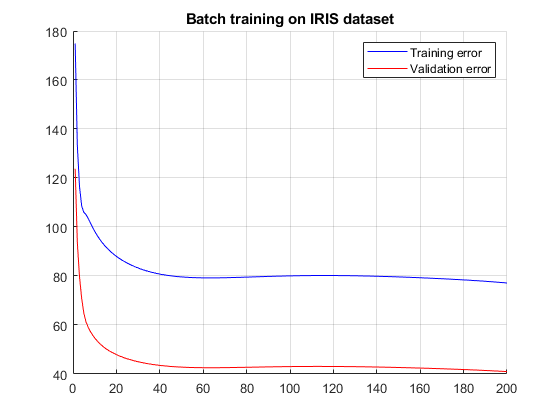

figure(), grid, hold on
plot(t_err, 'b'), plot(v_err, 'r')
legend('Training error', 'Validation error')
title('Batch training on IRIS dataset')

Let's repeat the test using a mini-batch approach, with 32 elements in each batch:

[t_err, v_err, best_net] = net.learn(X_t, T_t, X_v, T_v, 200, 0.0005, 32);

init err: 724.2842
epoch: 1, train_err: 708.2575, val_err: 243.3775
epoch: 2, train_err: 690.5014, val_err: 237.3201
epoch: 3, train_err: 688.17, val_err: 236.4556
epoch: 4, train_err: 685.8303, val_err: 235.5889
epoch: 5, train_err: 667.3556, val_err: 229.327
epoch: 6, train_err: 648.4922, val_err: 222.9415
epoch: 7, train_err: 630.6863, val_err: 216.7664
epoch: 8, train_err: 611.6122, val_err: 210.2785
epoch: 9, train_err: 593.9544, val_err: 204.1068
epoch: 10, train_err: 591.598, val_err: 203.2289
epoch: 11, train_err: 572.8697, val_err: 196.7881
epoch: 12, train_err: 555.7702, val_err: 190.7365
epoch: 13, train_err: 553.5341, val_err: 189.8894
epoch: 14, train_err: 535.3218, val_err: 183.5571
epoch: 15, train_err: 517.2458, val_err: 177.2566
epoch: 16, train_err: 500.8577, val_err: 171.3982
epoch: 17, train_err: 482.8303, val_err: 165.1466
epoch: 18, train_err: 466.4515, val_err: 159.3621
epoch: 19, train_err: 447.9331, val_err: 153.1013
epoch: 20, train_err: 431.0932, val_err: 147

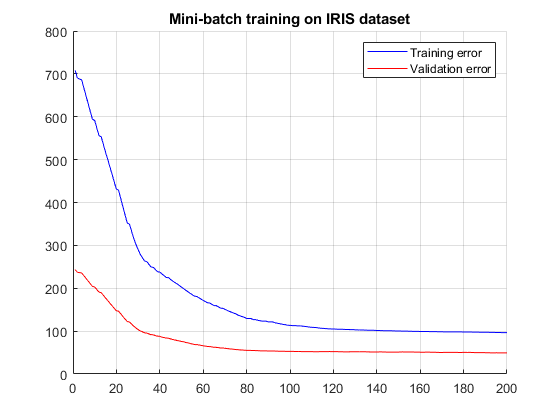

figure(), grid, hold on
plot(t_err, 'b'), plot(v_err, 'r')
legend('Training error', 'Validation error')
title('Mini-batch training on IRIS dataset')

Of course, you could implement an online learning, enable the weight-decay, update them using momentum, apply an early-stopping criterion, or create an arbitrary error function, as discussed in the previous sections.

#### A test on a more complex dataset: MNIST

Consider now the dataset MNIST, containing images of hand-written digits. Consider the first 3000 elements for the training set, and the next 1000 for the validation set.

clear variables
X = loadMNISTImages('mnist/train-images-idx3-ubyte');
L = loadMNISTLabels('mnist/train-labels-idx1-ubyte');
T = getTargetsFromLabels(L);
X_t = X(:,1:3000)';
T_t = T(:,1:3000)';
X_v = X(:,3001:4000)';
T_v = T(:,3001:4000)';

Now, build a network with 784 inputs (the number of pixel in each image), 50 internal nodes and 10 output nodes.

net = Network(784, [50 10]);
net.name = "mnist_net";

The learning is executed for 200 epochs, with a batch approach and learning rate $\eta =0\ldotp 0005$. Training and validation error are plotted.

[t_err, v_err, best_net] = net.learn(X_t, T_t, X_v, T_v, 200, 0.0005);

init err: 16320.8863
epoch: 1, train_err: 14946.1134, val_err: 5007.6474
epoch: 2, train_err: 13270.8445, val_err: 4460.6355
epoch: 3, train_err: 11454.7651, val_err: 3859.6048
epoch: 4, train_err: 10607.9011, val_err: 3580.3187
epoch: 5, train_err: 9255.3776, val_err: 3319.1368
epoch: 6, train_err: 10034.7113, val_err: 3360.3707
epoch: 7, train_err: 9837.3288, val_err: 3289.0347
epoch: 8, train_err: 8874.8593, val_err: 3053.7447
epoch: 9, train_err: 8223.125, val_err: 2912.998
epoch: 10, train_err: 5861.4004, val_err: 1978.0482
epoch: 11, train_err: 4782.3437, val_err: 1671.1788
epoch: 12, train_err: 3806.2182, val_err: 1386.1488
epoch: 13, train_err: 3543.2146, val_err: 1267.8903
epoch: 14, train_err: 3263.8531, val_err: 1175.1572
epoch: 15, train_err: 3122.6479, val_err: 1119.5528
epoch: 16, train_err: 2962.0912, val_err: 1065.8464
epoch: 17, train_err: 2855.2312, val_err: 1030.7937
epoch: 18, train_err: 2741.3114, val_err: 986.7318
epoch: 19, train_err: 2661.0764, val_err: 964.6742

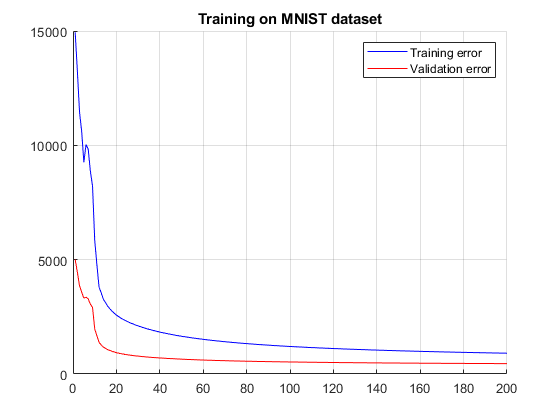

figure(), grid, hold on
plot(t_err, 'b'), plot(v_err, 'r')
legend('Training error', 'Validation error')
title('Training on MNIST dataset')

## Implementing a convolutional network

Similarly to the shallow network, the architecture of the convolutional network has been implemented with two classes: *ConvLayer* and *ConvNetwork*.

The **ConvLayer **class represents one convolutive layer of a deep network. The layer is made of up a number of feature maps and max pooling layers: the first ones are object of *Layer *type, while the latter got a proper implementation as an operation performed on the output of feature maps.

In order to create a convolutive layer, the following parameters are needed:

- dimension of inputs as a vector of three elements (volume)

- dimension of the filters as a vector of two elements (dimensions must be even, so that a center pixel can be identified)

- number of feature maps

- dimensions of max pooling windows as a vector of two elements

% Creating a convolutional layer that accepts as input an image from MNIST,
% uses 3x3 filters, has 5 feature maps and 2x2 max pooling windows

MyConvLayer = ConvLayer([28,28,1], [3,3], 5, [2,2]);

The **compute **function computes the output of the layer given the input, which dimensions must be coherent with the layer. The function returns three values: the first one is the output of the convolutive layer, as a three dimensional matrix (the third dimension is equal to the number of feature maps); the second one is a cell array containing the outputs of the feature maps; the third one containts the indices of the elements selected by the max pooling.

% Example
[ConvLayerOutput, FeatureMapsOutput] = compute(MyConvLayer, randn(28,28,1));

The **ConvNetwork** class represents a convolutional network: it accepts a volumetric input, and contains any number of layers, each one with any number of feature maps, and with filters of any dimensions.

In order to create a *ConvNetwork* you need to specify the dimensions of input and output, the number of layers and feature maps, and the dimensions of the filters. 

For example, in order to create a network that accepts a 30x30 pixels RGB image (3 channels), 4 outputs, two layers with 10 and 5 feature maps respectively, and 3x3 filters:

net = ConvNetwork([30, 30, 3], 4, [10, 5], [3, 3]);

*ConvNetwork* has the same structure as *Network;* you can specify its name, define a new error function or use the ones already implemented in the library - cross entropy with softmax (default) or sum of squares. The learning function's synax is the same too, so you can specify:

- training and validation set

- number of epochs

- weight update algorith, like R-prop (default) or gradient descent and its hyperparameters

- batch approach (default), mini-batch (of any dimensions) or online

- enabling or disabling weight-decay

- enabling or disabling weight update using momentum

- an early stopping criterion: *"firstMin" *or *"stopEpochs"*, like defined in the section regarding the *Network *class

Since the convolutional network is the same structure of the shallow network, there is no example here on how to use it; instead, the problem of classification of MNIST images is tackled in the next section.

## Classifying hand-written digits (MNIST) using a convolutional network

Consider the classification problem of the *MNIST* dataset, containing images of hand-written digits using a convolutional network. These are gray-scale 28x28 image, thus defined on a single channel, classified in 10 classes of course.

The *test.m *script loads the dataset, initializes the network, trains it and memorizes the resulting accuracy. At the beginning of the script, you can find all the parameters that define the network's behaviour: in this way, it is straightforward to modify the values you need and execute the script.

### Choosing the hyperparameters

In order to test the network, different set of parameters has been used and the different outputs compared. A value of $\eta =\left\lbrack 0\ldotp 5,\;1\ldotp 02\right\rbrack$ is capable of giving a sufficiently rapid convergence, as well as avoiding local minima and numerical instability.

At this point, a *"grid" *approach has been used, in order to have a complete and exhaustive vision of the network behaviour while varying its parameters. In particular, regarding a single convolutive layer, we tested the use of 5, 10, 15, and 20 feature maps, and each test has been repetead with filters of dimensions 3x3, 5x5, 7x7 e 9x9.

Because of the long time needed for the learning stage, each test has been executed only once, and their results saved on files in the *results *directory; also, these tests have been executed on a limited number of data and epochs. The networks that gave the best results have been trained several times using much more data and epochs, in order to obtain different accuracy values: average and standard deviation have been computed.

### Tests with a single convolutive layer

The two most promising architectures of the network with only one convolutive layer are the one with 10 feature maps and 3x3 filters, and the one with 15 feature maps and 5x5 filters. These networks have been trained on a training set containing 1000 elements, while validation set and test set consist of 500 elements.

The results of the test of the first network are loaded, the accuracy is computed, and training and validation error are plotted.

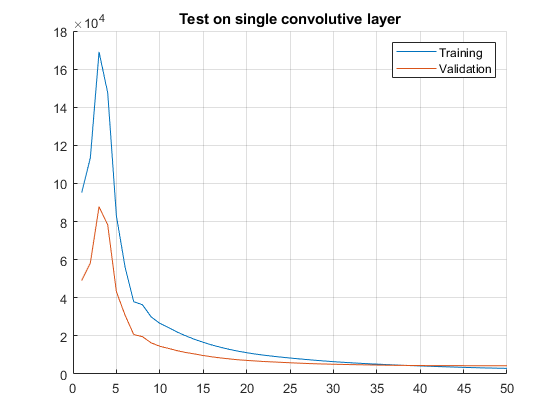

load('results/10map_filterDim3x3_LONG(1)');

% Plot
figure(), grid, hold on

plot(terr), plot(verr)
legend('Training', 'Validation')
title('Test on single convolutive layer')

exact: 389; total: 500; accuracy: 0.778



% Accuracy
disp(['exact: ', num2str(exact), '; total: ', num2str(testDim), '; accuracy: ', num2str(accuracy)]);

Due to the long time needed for the program execution, only three different measurements have been realized. The three accuracies are loaded, and their average and variance are computed:

testNum = 3;               % Number of tests
meas = zeros(1,testNum);   % Measurements
for i = 1 : testNum
    % Load only the accuracy
    load(['results/10map_filterDim3x3_LONG(', num2str(i), ')'], 'accuracy');
    meas(i) = accuracy;
end

Accuracies: 0.778        0.81       0.798


disp(['Accuracies: ', num2str(meas)]);

Mean: 0.79533


disp(['Mean: ', num2str(mean(meas))]);

Std: 0.016166


disp(['Std: ', num2str(std(meas))]);

The same is done for the second network:

testNum = 3;               % Number of tests
meas = zeros(1,testNum);   % Measurements
for i = 1 : testNum
    % Load only the accuracy
    load(['results/15map_filterDim5x5_LONG(', num2str(i), ')'], 'accuracy');
    meas(i) = accuracy;
end
disp(['Accuracies: ', num2str(meas)]);

Accuracies: 0.808       0.804        0.83


disp(['Mean: ', num2str(mean(meas))]);

Mean: 0.814


disp(['Std: ', num2str(std(meas))]);

Std: 0.014


The second network got better performances than the first one: in both case, however, results are consistent (standard deviation is small) and satisfying, considering that the network has been trained on a small training set.

### Tests with more convolutive layers

Networks with more convolutive layers has been considered too. Due to computational reasons, even smaller datasets has been used: only 500 elements for the training set, 250 elements for validation and test sets.

The results are much worse than the previous model with just one layer: however, an investigation on a much bigger dataset is needed before giving conclusions. The best results was given by a network with 2 layers, with 10 and 15 feature maps respectively, using 3x3 filters.

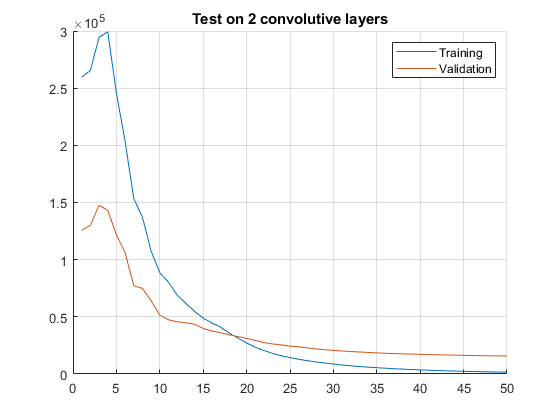

load('results/2layers_10_15map_filterDim3x3');

% Plot
figure(), grid, hold on
plot(terr), plot(verr)
legend('Training', 'Validation')
title('Test on 2 convolutive layers')


% Accuracy
disp(['exact: ', num2str(exact), '; total: ', num2str(testDim), '; accuracy: ', num2str(accuracy)]);

exact: 179; total: 250; accuracy: 0.716


### **Further improvements**

The network developed in this project gave good results, but chances of further improvements and developments are clear, as well as the obtainable performances. In particular:

- train the networks on much bigger dataset, that have been severly limited by time and computational requirements. The whole *MNIST* dataset is composed by 60k elements, while in this project we used at maximum 2k elements.

- use filters of different dimensions for each layer, or a padding different from 1

- test different weight update algorithms (in this project, batch and rProp were required)